MAKING OF A DISCRETE TIME SIGNAL: SINE WAVE WITH 1kHz.

f = 1000 % 1kHz. frequency as on the colleague-plot

f = 1000


f_s = 8000 %Choosing a sampling frequency higher than the Nyquist (2*3000kHz.)

f_s = 8000


delta_f = 2 % frequency resolution as on the colleague plot

delta_f = 2


T = 1/delta_f % time duration

T = 0.5000


delta_t = 1/f_s % time resolution

delta_t = 1.2500e-04


N_s = T/delta_t % total number of samples of clean 1kHz. signa

N_s = 4000



t = 0:1/f_s:N_s-1/f_s; % time vector for the signal s
s = sin(2*pi*f*t); % signal s: the clean 1kHz. signal


% Making an interval of the signal so that we can visualize it properly
t_s_min = find(t >=0.16);
t_s_max = find(t >=0.166);
t_s_interval = t(t_s_min:t_s_max);
s_interval = s(t_s_min:t_s_max);

% Making the frequency spectrum of s using the FFT in the function
% make_spectrum
[Y_s, freq_s] = make_spectrum(s, f_s);
freq_min_s = find(freq_s >=0);
freq_max_s = find(freq_s >=3000);
freq_s_interval = freq_s(freq_min_s:freq_max_s);
Y_s_int = Y_s(freq_min_s:freq_max_s);



RECORDING OF MY OWN VOICE ("piiift") appr. at 1kHz. :-)

info_piift =audioinfo("piift_trimmed_0.5s.wav") % file info (duration T=0,5s)

info_piift = struct with fields:
             Filename: 'C:\Users\asgra\OneDrive\Dokumenter\DTU\5. semester\Signals and systems in discrete time\assignment1_individual\piift_trimmed_0.5s.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 44100
         TotalSamples: 22050
             Duration: 0.5000
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16



[data_piift, fs_piift] = audioread("piift_trimmed_0.5s.wav"); % read in the .wav file

N_piift = length(data_piift) % total number of samples

N_piift = 22050


data_piift = data_piift./max(abs(data_piift)); % Normalizing the signal so it becomes easier to compare

% Making an interval (same as for s) of the signal so that we can visualize it properly and
% compare with the "clean" 1Khz. signal in the time domain
t_piift = (0:length(data_piift)-1)/fs_piift;
t_piift_min = find(t_piift >=0.16);
t_piift_max = find(t_piift >=0.166);
t_piift_interval = t_piift(t_piift_min:t_piift_max);
data_piift_interval = data_piift(t_piift_min:t_piift_max);

% Using FFT with function make_spectrum to generate the fourier transform
% of my voice recording
[Y_piift, freq_piift] = make_spectrum(data_piift, fs_piift);
freq_min = find(freq_piift >=0);
freq_max = find(freq_piift >=3000);
freq_piift_interval = freq_piift(freq_min:freq_max);
Y_piift_int = Y_piift(freq_min:freq_max);


COMPARING THE CLEAN 1kHz. SIGNAL WITH MY VOICE (PIIFT) IN THE TIME DOMAIN AND FREQUENCY DOMAIN

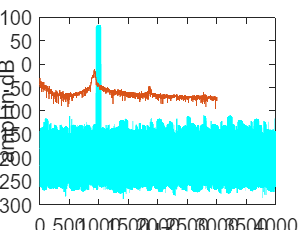

% Time domain plot: the clean signal vs. voice recording
figure;
plot(t_s_interval,s_interval, LineWidth=1.5);
xlabel('t (sec)');
ylabel('amplitude normalized')
hold on
plot(t_piift_interval, data_piift_interval, LineWidth=1.5);
hold off

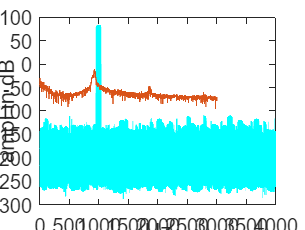


% Frequency domain plot: the clean signal vs. voice recording
figure;
plot(freq_s_interval, mag2db(2.*abs(Y_s_int)/N_s), '-c', LineWidth=3);
xlabel('Hz');
ylabel('ampl in dB');
hold on
plot(freq_piift_interval, mag2db(2.*abs(Y_piift_int)/N_piift));
hold off

QUESTIONS: 

DO I NEED TO MAKE MY PLOT OF MY VOICE A LITTLE SHORTER?

DO MY VOICE RECORDING ALSO DEPEND UPON THE SAMPLING FREQUENCY?